## Introduction

In this scrip we want to make the RMS curve smooth.

## Import Data

Fixed parameters

Total_experiment_number=3000;
delta=0.01;
dataloication='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\v4_1\data'

dataloication = 'C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\v4_1\data'

H=0.6

H = 0.6000

zeta=100

zeta = 100

psi=zeta/5

psi = 20

import and smoothing

%load([dataloication,'\RMSdata.H=',num2str(H),'.zeta=',num2str(zeta),'.psi=',num2str(psi),'.N=',num2str(Total_experiment_number),'.mat']);
data_name='p47_5s'

data_name = 'p47_5s'

load(['C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\MSDData4Quan_20210905\MSD_',data_name,'_All.mat'])
RMSX=eval(['MSD_',data_name,'_All']).MSD_PP(:,1)

RMSX = 	1.0e+05 *

    0.4182
    0.5573
    0.6495
    0.7234
    0.7759
    0.8086
    0.8435
    0.8772
    0.9085
    0.9322


X=1:107

X =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


plotfit

n=4

n = 4

p=polyfit(X,RMSX,n)

p = 	1.0e+04 *

    0.0000   -0.0001    0.0002    0.1937    6.6322


x1 = linspace(1,107);
y1 = polyval(p,x1);
y2=interp1(X,RMSX,x1,'pchip');

plotting

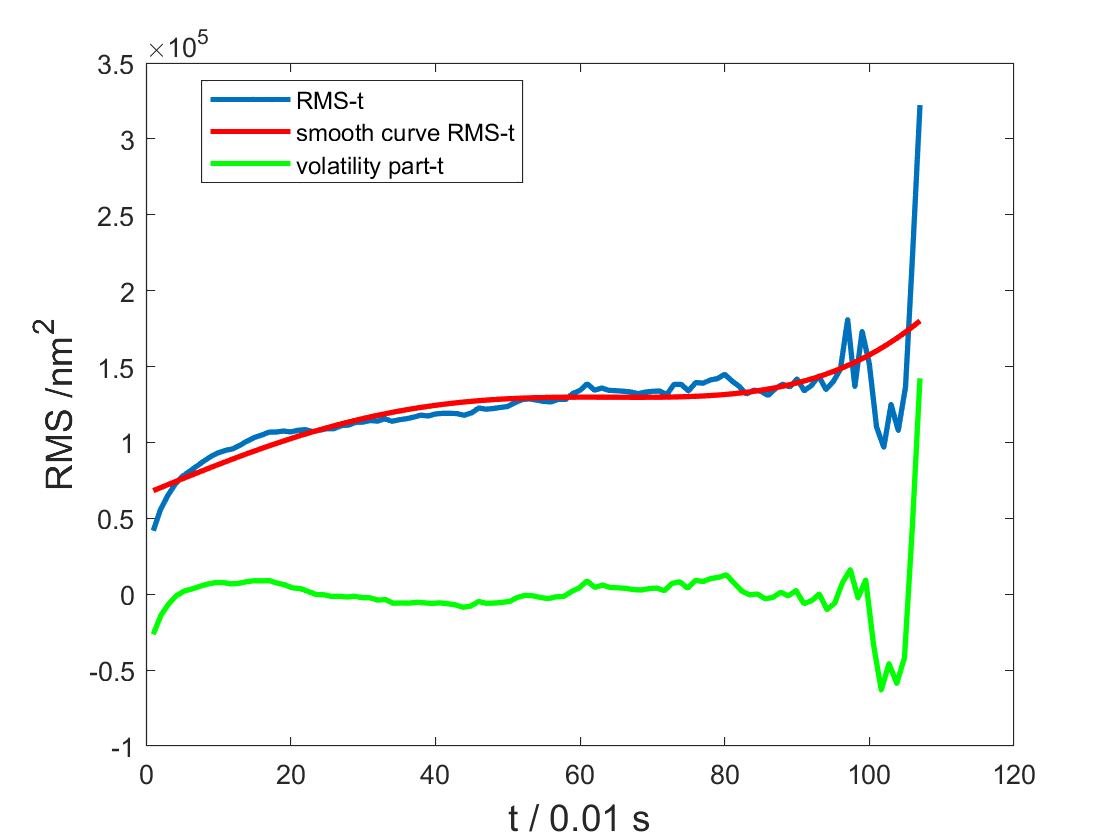

figure
plot(X,RMSX,'LineWidth',2);
hold on
plot(x1,y1,'LineWidth',2,'Color','r')
plot(x1,y2-y1,'LineWidth',2,'Color','g')
xlabel(['t / ',num2str(delta),' s'],'FontSize',14);
ylabel('RMS /nm^2','FontSize',14);
%title(['smooth curve (n=',num2str(n),') & volatility part RMS-t: ',' H=',num2str(H),' \zeta=',num2str(zeta),' \psi= ',num2str(psi),' \Deltat= ',num2str(delta), ...
%    ' N= ',num2str(Total_experiment_number)],'FontSize',16);
legend('RMS-t','smooth curve RMS-t','volatility part-t','Location',"best");
saveas(gcf,['v8\processed_image\smooth_RMS','.n=',num2str(n),'.H=',num2str(H),'.zeta=',num2str(zeta),'.psi=',num2str(psi),'.delta=',num2str(delta),'.N=',num2str(Total_experiment_number),'.jpg'])

## frequecy of volatility part